# The FITS static class

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

The `FITS` is a static class that supports read, write and manipulation of Flexible Image Transport Files (FITS). FITS are commonly used astronomical image file format, and FITS utilities and standards are being developed by the[ FITS support office](https://fits.gsfc.nasa.gov/).

MATLAB has a full support of high level and low level FITS functions and can call the [FITS/IO library](https://www.mathworks.com/help/matlab/flexible-image-transport-system.html). This static class provide additional high level functions.

This file is accessible through the `manual` package (i.e. `manual.FITS`). 

We note that reading and writing FITS files is slow relative to simple arithmatic operations. This is one of the reasons why the philosophy of the image reduction tools in the astronomy and astrophysics toolbox is to use the in-memory [SIM object](https://webhome.weizmann.ac.il/home/eofek/matlabn/doc/SIM.html). `SIM` object is simply a container for astronomical images and it can be associated with additional meta data like, header, WCS, catalogs, PSF, background image, noise image, weight image and mask image. The `FITS` static class support also reading FITS files into `SIM` objects.

We note that reading and writing HDF5 files is an order of magnitude faster than reading and writing FITS files, and it is useful to inspect this alternative. Support for this option is TBD.

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

# Methods and examples

## Reading FITS images into SIM

The most basic operation is reading a FITS file:

The `FITS.read2sim` method can be used to read FITS files into `SIM` objects:

S=FITS.read2sim('test_PTF*.fits')

Various file input methods are supported. The first argument (the list of file names) is being parsed using the Util.files.create_list function (see help Util.files.create_list for details). For example, one can read file names listed in a file:

%S=FITS.read2sim('@file');

or use wild cards and number ranges (note that more than one digit range is supported):

% doen't work - need to fix bug!
S=FITS.read2sim('test_PTF_20[12-16]*.fits')

S =   SIM with properties:

               Im: []
    ImageFileName: ''
           BackIm: []
            ErrIm: []
         WeightIm: []
              Cat: []
              Col: []
          ColCell: []
         ColUnits: []
         SortedBy: []
      SortedByCol: []
             Name: []
           Source: []
        Reference: []
          Version: []
           Header: {0×3 cell}
              WCS: []
         UserData: []
             Mask: []
          MaskDic: []
              PSF: []
           ErrPSF: []
           ParPSF: {}
           CooPSF: []


or a cell array of files:

cd ~/matlab/images
[~,Cell] = Util.files.create_list('test_PTF*.fits',NaN)

Cell =     'test_PTF_201205233056_i_p_scie_t072001_u013342353_f02_p004162_c08.fits'    'test_PTF_201606123141_i_p_scie_t073220_u027914930_f02_p004162_c08.fits'


S=FITS.read2sim(Cell);

One can also read FITS image sections:

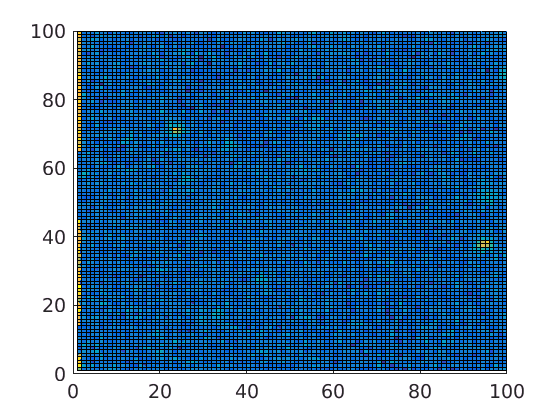

S=FITS.read2sim('test_PTF*.fits','CCDSEC',[1 100 1 100]);
surface(S(1).Im)

For details regarding additional options see help `FITS.read2sim`.

## Reading FITS images into an array

The following example read a section of a FITS file into an array (the default is to read the entire image):

cd ~/matlab/images
[~,Cell] = Util.files.create_list('test_PTF*.fits',NaN)

Cell =     'test_PTF_201205233056_i_p_scie_t072001_u013342353_f02_p004162_c08.fits'    'test_PTF_201606123141_i_p_scie_t073220_u027914930_f02_p004162_c08.fits'


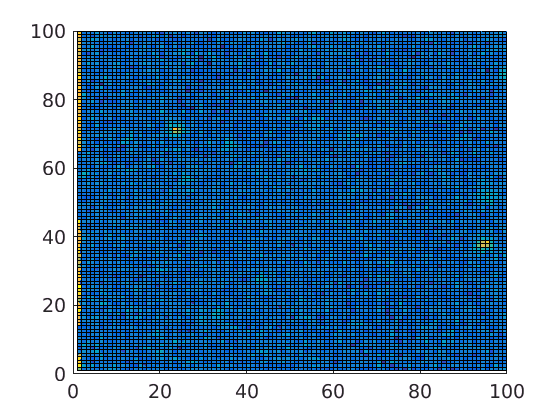

Im=FITS.read(Cell{1},[],[11 11],[70 70]);
surface(Im)

or you can read a list of FITS images (with the same size) into a cube, where the first dimension is the image index.

S=FITS.read2cube('test_PTF*.fits');
size(S)

ans =            2        4096        2048


The function `FITS.fitsread` call the internal matlab FITS file reader.

## Read FITS tables

You can use `FITS.read_table` to read FITS tables.

## Writing FITS images

You can use `FITS.fitswrite`, FITS.write and FITS.write_old to write FITS images. For example:

Flag=FITS.write(rand(100,100),'TryTry.fits');
!rm TryTry.fits

## The header

There are several functions for reading, editing and manipulating FITS headers and keywords. To read the FITS header (only) into an HEAD object (see separate documentation):

H=FITS.get_head('test_PTF*.fits')

H =   1×2 HEAD array with properties:

    Header
    WCS
    UserData


The FITS.head command can be used to display the FITS header of a single file (either a file or an HEAD object):

FITS.head(H(1))

ans =   SIMPLE                 NaN Fits standard
  BITPIX      -32.0000000000 FOUR-BYTE SINGLE PRECISION FLOATING POINT
   NAXIS        2.0000000000 STANDARD FITS FORMAT
  NAXIS1     2048.0000000000 STANDARD FITS FORMAT
  NAXIS2     4096.0000000000 STANDARD FITS FORMAT
  ORIGINPalomar Transient Factory Origin of these image data
 CREATORInfrared Processing and Analysis Center Creator of this FITS file
TELESCOP            P48      Name of telescope
INSTRUME          PTF/MOSAIC Instrument name
OBSERVER         KulkarniPTF Observer name and project
   CCDID            8        CCD number (0..11)
DATE-OBS2012-05-23T07:20:01.937 UTC shutter time YYYY-MM-DDTHH:MM:SS.SSS
    DATE 2012-05-23T09:28:46 File creation date (YYYY-MM-DDThh:mm:ss UT)
REFERENChttp://www.astro.caltech.edu/ptf' / URL of PTF websiteptf' / URL of PTF website
 PTFPRPI            Kulkarni PTF Project PI
  PTFPID            30011    Project type: 00000-49999
  OBJECT          PTF_survey Fields object
PTFFIELD            4162

We note that the HEAD class provide many more powerfull functions to work with header information.

The function `FITS.num_hdu` return the number of header data units (HDU)  available ina FITS file.

## Keywords manipulation

To read specific keywords directly from the FITS header:

[KeysVal,KeysComment,Struct]=FITS.get_keys('test_PTF_201205233056_i_p_scie_t072001_u013342353_f02_p004162_c08.fits',{'NAXIS1','NAXIS2'})

KeysVal =     '2048'    '4096'


KeysComment =     'STANDARD FITS FORMAT'    'STANDARD FITS FORMAT'


Struct =     NAXIS1: '2048'
    NAXIS2: '4096'


The function FITS.mget_keys can be used to read FITS header keywords from multiple FITS files:

[KeysVal,KeysComment]=FITS.mget_keys('_test_PTF*.fits',{'NAXIS1','NAXIS2'});

You can also write new keywords to a FITS header using `FITS.write_keys`, and the functions `FITS.get_sip `and `FITS.get_tpv `can be used to read the specific WCS keywords from a FITS header.

## Additional functions

There are several other functions FITS.cellhead_* which can be used to manipulate the 3 column cell array in which the FITS header is stored.